# Task 1a: SIR model in MATLAB

Initial values for each class:

S0 = 20;
I0 = 15;
R0 = 10;

Recruitment rate:

a = 3;

Natural death rate:

d = 0.1;

Proportionality constant:

lambda = 1.3; % completely removed (in S(t) and I(t))

Rate of immunity loss:

beta = 0.1; % partially removed (in S(t))

Natural recovery rate:

m = 0.01; % completely removed (in I(t) and R(t))

Parameters for psychological and inhibitory effect:

alpha1 = 1; % partially replaced with alpha2 (in S(t))
alpha2 = 0.1;

Unclear parameters:

r = 0.2; % used if 0 < I <= I0
k1 = 0.2; % used if I > I0

Construction of T, S(t), I(t) and R(t):

tmax = 200;

S = zeros(1, tmax + 1);
I = zeros(1, tmax + 1);
R = zeros(1, tmax + 1);
    
S(1) = S0;
I(1) = I0;
R(1) = R0;
    
T(1) = 0;

for t = 1:tmax
        
    T(t+1) = t;
        
    % S(t+1)=S(t)+(a-d*S(t)-(lambda*S(t)*I(t)/(1+alpha1*I(t)+alpha2*I(t)^2))+beta*R(t));
    S(t+1) = S(t) + (a-d*S(t) - (S(t)*I(t)/(1+alpha2*I(t) + alpha2*I(t)^2)));
    
    % I(t+1)=I(t)+((lambda*S(t)*I(t)/(1+alpha1*I(t)+alpha2*I(t)^2))-(d+m+r)*I(t));
    I(t+1) = I(t) + ((S(t)*I(t)/(1+alpha1*I(t) + alpha2*I(t)^2)) - (d+r)*I(t));
    
    % R(t+1)=R(t)+(m*I(t)-(d+beta)*R(t)+r*I(t));
    R(t+1) = R(t) - (d+beta)*R(t) + r*I(t);
        
end

Visualisation of the model:

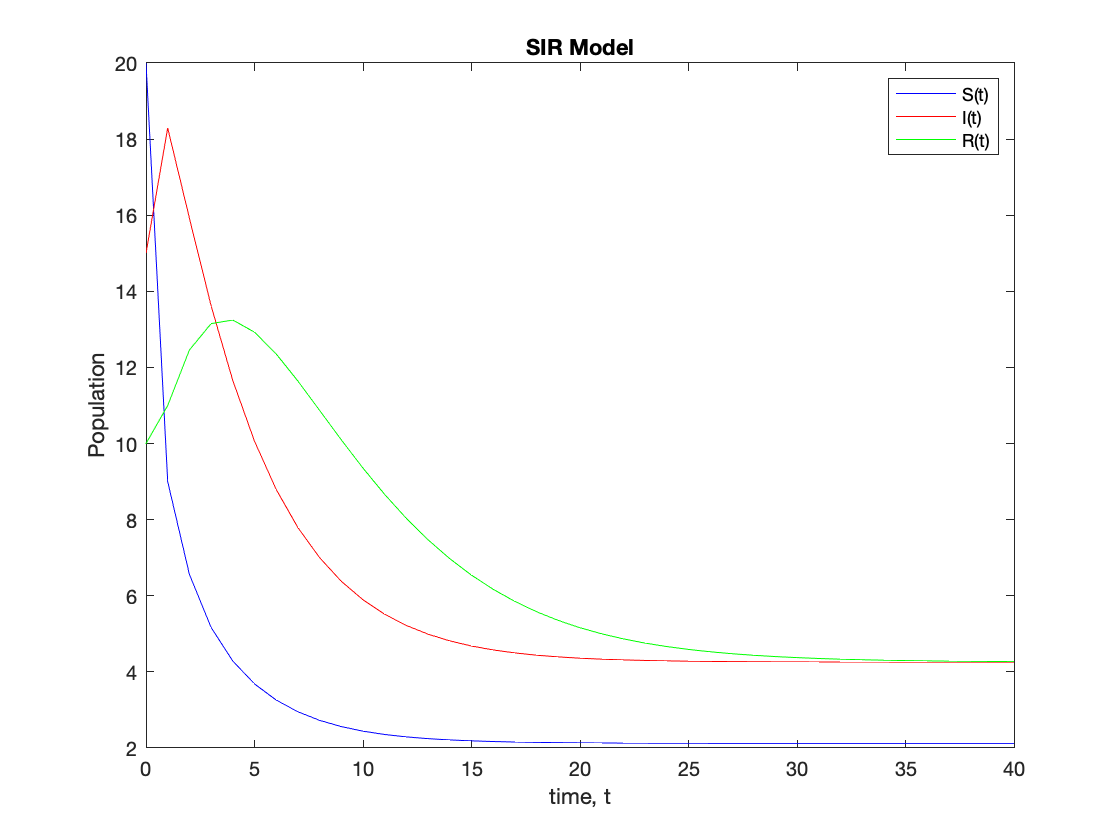

plot(T, S, 'b')

hold on
plot(T, I, 'r')
plot(T, R, 'g')

title('SIR Model')
legend('S(t)', 'I(t)', 'R(t)')

xlabel('time, t')
ylabel('Population')

xlim([0 40])

hold off